# Entrega L4 - Opció C

## Exercici  2

### Apartat A

clear
format short g

any = [1975 1980 1985 1990 1995 2000 2005 2010]';
vida = [73.3 75.3 76.2 76.8 78 79 80.2 81.6]';
T = table(any,vida)

T = 8×2 table
    any     vida
    ____    ____

    1975    73.3
    1980    75.3
    1985    76.2
    1990    76.8
    1995      78
    2000      79
    2005    80.2
    2010    81.6


[p,~,mu]= polyfit(T.any,T.vida,7);

a1=polyval(p,1970,[],mu);
error= abs(72 - a1)

error =          13.2



a2=polyval(p,1992,[],mu);
error= abs(77.4 - a2)

error =       0.15518


a3= polyval(p,2007,[],mu);
error= abs(80.9 - a3)

error =      0.080309


### Apartat B

s1 = splinetx(any,vida,1970);
error= abs(72 - s1)

error =        2.4263


s2=splinetx(any,vida,1992);
error= abs(77.4 - s2)

error =       0.15697


s3=splinetx(any,vida,2007);
error= abs(80.9 - s3)

error =       0.15133


### Apartat C

[p1,~,mu1]= polyfit(T.any,T.vida,1);
[p2,~,mu2]= polyfit(T.any,T.vida,2);
[p3,~,mu3]= polyfit(T.any,T.vida,3);
[p4,~,mu4]= polyfit(T.any,T.vida,4);

e1= 0;
e1 = e1 + abs(72 - polyval(p1,1970,[],mu1));
e1 = e1 + abs(77.4 - polyval(p1,1992,[],mu1));
e1 = e1 + abs(80.9 - polyval(p1,2007,[],mu1));
e1 = e1/3;

e2= 0;
e2 = e2 + abs(72 - polyval(p2,1970,[],mu2));
e2 = e2 + abs(77.4 - polyval(p2,1992,[],mu2));
e2 = e2 + abs(80.9 - polyval(p2,2007,[],mu2));
e2 = e2/3;

e3= 0;
e3 = e3 + abs(72 - polyval(p3,1970,[],mu3));
e3 = e3 + abs(77.4 - polyval(p3,1992,[],mu3));
e3 = e3 + abs(80.9 - polyval(p3,2007,[],mu3));
e3 = e3/3;

e4= 0;
e4 = e4 + abs(72 - polyval(p4,1970,[],mu4));
e4 = e4 + abs(77.4 - polyval(p4,1992,[],mu4));
e4 = e4 + abs(80.9 - polyval(p4,2007,[],mu4));
e4 = e4/3;

elms= [e1 e2 e3 e4]

elms =       0.27262      0.27524      0.31894      0.79498


[m, i] = min(elms); i

i =      1


En el nostre cas el millor es el polinomi de grau 1

### Apartat D

% Pol. grau 7 %

% 1970
a1, abs(72 - a1)

a1 =          85.2


ans =          13.2


% 2015
a4=polyval(p,2015,[],mu), abs(83.4 - a4)

a4 =          67.5


ans =          15.9


% Spline %

% 1970
s1, err= abs(72 - s1)

s1 =        69.574


err =        2.4263


% 2015
s4 = splinetx(any,vida,2015), err= abs(83.4 - s4)

s4 =        82.974


err =       0.42632


% Pol. grau 1 %

% 1970
g1= polyval(p1,1970,[],mu1), err= abs(72 - g1)

g1 =        72.611


err =       0.61071


% 2015
g2= polyval(p1,2015,[],mu1), err= abs(83.4 - g2)

g2 =        82.489


err =       0.91071


### Apartat E

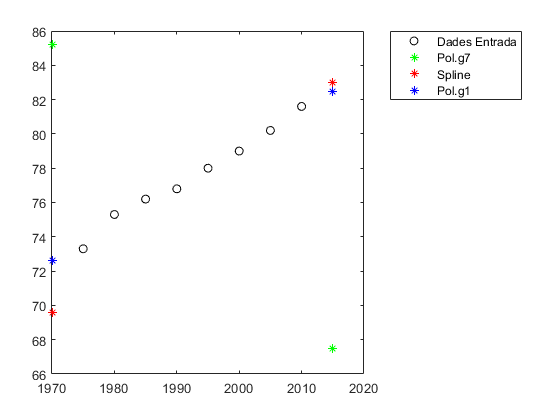

x= [1970,2015];
grau7y= [a1,a4];
spl= [s1,s4];
grau1y= [g1,g2];

plot(any,vida,'ok',x,grau7y,'*g',x,spl,'*r',x,grau1y,'*b'),legend('Dades Entrada','Pol.g7','Spline','Pol.g1','Location','bestoutside')

## Exercici 3

### Apartat A

clear
format short g
x0= sqrt(2);
sol= 1/3;
f=@(x)atan(x);

k=1:6;
h= 2.^-k;

for n=1:6
    fp(n)= (f(x0+h(n)) - f(x0))/h(n);
end
err= abs(fp-sol);
res=[k;h;fp;err]'

res =             1          0.5      0.26813     0.065199
            2         0.25      0.29764     0.035693
            3        0.125      0.31462     0.018711
            4       0.0625      0.32375     0.009584
            5      0.03125      0.32848    0.0048507
            6     0.015625      0.33089    0.0024402


### Apartat B i C

q=2;
N1 = @(h) (f(x0 + h) - f(x0))/h;
N2 = @(h) N1(h/q) + (N1(h/q) - N1(h))/((q.^1)-1);
N3 = @(h) N2(h/q) + (N2(h/q) - N2(h))/((q.^2)-1);
N4 = @(h) N3(h/q) + (N3(h/q) - N3(h))/((q.^3)-1);

for n=1:6
    rich1(n,1) = h(n);
    rich1(n,2) = N1(h(n));
    rich1(n,3) = funerror(rich1(n,2),1/3);
    xifres1(n) = correctDec(rich1(n,2),1/3);
end
for n=2:6
    rich2(n,1) = h(n-1);
    rich2(n,2) = N2(h(n-1));
    rich2(n,3) = funerror(rich2(n,2),1/3);
    xifres2(n) = correctDec(rich2(n,2),1/3);
end

for n=3:6
    rich3(n,1) = h(n-2);
    rich3(n,2) = N3(h(n-2));
    rich3(n,3) = funerror(rich3(n,2),1/3);
    xifres3(n) = correctDec(rich3(n,2),1/3);
end

for n=4:6
    rich4(n,1) = h(n-3);
    rich4(n,2) = N4(h(n-3));
    rich4(n,3) = funerror(rich4(n,2),1/3);
    xifres4(n) = correctDec(rich4(n,2),1/3);
end

R1= table(rich1(:,1),rich1(:,2),rich1(:,3)); R1.Properties.VariableNames={'h','Rich1','Err'}

R1 = 6×3 table
       h         Rich1        Err   
    ________    _______    _________

         0.5    0.26813     0.065199
        0.25    0.29764     0.035693
       0.125    0.31462     0.018711
      0.0625    0.32375     0.009584
     0.03125    0.32848    0.0048507
    0.015625    0.33089    0.0024402


R2= table(rich2(:,1),rich2(:,2),rich2(:,3)); R2.Properties.VariableNames={'h','Rich2','Err'}

R2 = 6×3 table
       h        Rich2        Err    
    _______    _______    __________

          0          0             0
        0.5    0.32715     0.0061861
       0.25     0.3316     0.0017296
      0.125    0.33288    0.00045694
     0.0625    0.33322    0.00011738
    0.03125     0.3333    2.9742e-05


R3= table(rich3(:,1),rich3(:,2),rich3(:,3)); R3.Properties.VariableNames={'h','Rich3','Err'}

R3 = 6×3 table
      h        Rich3        Err    
    ______    _______    __________

         0          0             0
         0          0             0
       0.5    0.33309    0.00024409
      0.25     0.3333    3.2715e-05
     0.125    0.33333    4.1946e-06
    0.0625    0.33333    5.2928e-07


R4= table(rich4(:,1),rich4(:,2),rich4(:,3)); R4.Properties.VariableNames={'h','Rich4','Err'}

R4 = 6×3 table
      h       Rich4        Err    
    _____    _______    __________

        0          0             0
        0          0             0
        0          0             0
      0.5    0.33333    2.5181e-06
     0.25    0.33333    1.2035e-07
    0.125    0.33333    5.6541e-09


### Apartat D

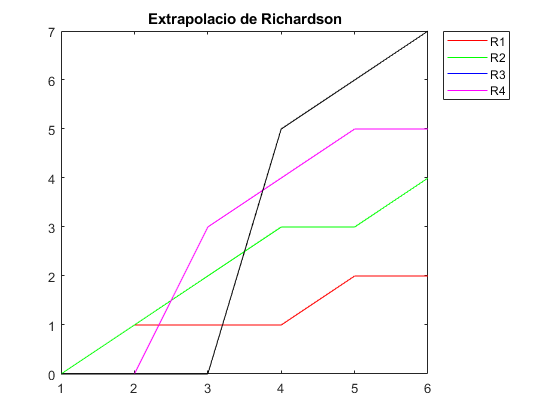

dAprox= [0 1 1 1 2 2];
plot(k,xifres1,'r',k,xifres2,'g',k,xifres3,'b',k,xifres3,'m',k,xifres4,'k'),legend('R1','R2','R3','R4','Location','bestoutside'),title('Extrapolacio de Richardson')

En la primera formula tots el noma= bres tenen almenys un decimal correcte mentre que mitjançant richardson no en tenen cap.

## Exercici 4

### Apartat A

clear
format short g

f=@(t)(1/(t-1));
a=2; b=3;
k=0:5;
h= 2.^-k;
TRAP= zeros(1,size(h,2));

for n=1:size(h,2)
    TRAP(n)= h(n)/2 * (f(a)+2*calcIntX(a,b,h(n),f)+f(b));
end
errTrap= abs(log(2) - TRAP);
TTrap= table(h',TRAP',errTrap'); TTrap.Properties.VariableNames = {'h','Trap','Err'}

TTrap = 6×3 table
       h        Trap         Err    
    _______    _______    __________

          1       0.75      0.056853
        0.5    0.70833      0.015186
       0.25    0.69702     0.0038766
      0.125    0.69412    0.00097467
     0.0625    0.69339    0.00024402
    0.03125    0.69321    6.1028e-05


### Apartat B*

SIMP= zeros(1,size(h,2));
for n= 1:size(h,2)
    SIMP(n)=  h(n)/3 * ( f(a) + f(b) + getFn(a,b,h(n),f));
end
errSimp= abs(log(2) - SIMP);
TSimp= table(h',SIMP',errSimp'); TSimp.Properties.VariableNames = {'h','Simp','Err'}

TSimp = 6×3 table
       h        Simp         Err    
    _______    _______    __________

          1        0.5       0.19315
        0.5    0.69444     0.0012973
       0.25    0.69325    0.00010679
      0.125    0.69315    7.3501e-06
     0.0625    0.69315    4.7226e-07
    0.03125    0.69315     2.973e-08


### Apartat B

RombergDisp(f,a,b,5);

0.750000000000000
0.708333333333333	0.694444444444444	
0.697023809523809	0.693253968253968	0.693174603174603	
0.694121850371850	0.693154530654531	0.693147901481235	0.693147477644832	
0.693391202207527	0.693147652819419	0.693147194297078	0.693147183071933	0.693147181916745	
0.693208208269249	0.693147210289823	0.693147180787850	0.693147180573418	0.693147180563620	0.693147180562297	


romb1= [0.750000000000000 0.708333333333333 0.697023809523809 0.694121850371850 0.693391202207527 0.693208208269249];
romb2= [0 0.694444444444444 0.693253968253968 0.693154530654531 0.693147652819419 0.693147210289823];
romb3= [0 0 0.693174603174603 0.693147901481235 0.693147194297078 0.693147180787850];
romb4= [0 0 0 0.693147477644832 0.693147183071933 0.693147180573418];

TRomb= table(h',romb1',romb2',romb3',romb4'); TRomb.Properties.VariableNames = {'h','Romb1','Romb2','Romb3','Romb4'}

TRomb = 6×5 table
       h        Romb1      Romb2      Romb3      Romb4 
    _______    _______    _______    _______    _______

          1       0.75          0          0          0
        0.5    0.70833    0.69444          0          0
       0.25    0.69702    0.69325    0.69317          0
      0.125    0.69412    0.69315    0.69315    0.69315
     0.0625    0.69339    0.69315    0.69315    0.69315
    0.03125    0.69321    0.69315    0.69315    0.69315


TRombErr= table(h',abs(log(2)-romb1)',abs(log(2)-romb2)',abs(log(2)-romb3)',abs(log(2)-romb4)'); TRombErr.Properties.VariableNames = {'h','Romb1','Romb2','Romb3','Romb4'}

TRombErr = 6×5 table
       h         Romb1         Romb2         Romb3         Romb4   
    _______    __________    __________    __________    __________

          1      0.056853       0.69315       0.69315       0.69315
        0.5      0.015186     0.0012973       0.69315       0.69315
       0.25     0.0038766    0.00010679    2.7423e-05       0.69315
      0.125    0.00097467    7.3501e-06    7.2092e-07    2.9708e-07
     0.0625    0.00024402    4.7226e-07    1.3737e-08     2.512e-09
    0.03125    6.1028e-05     2.973e-08     2.279e-10    1.3473e-11


### Apartat C

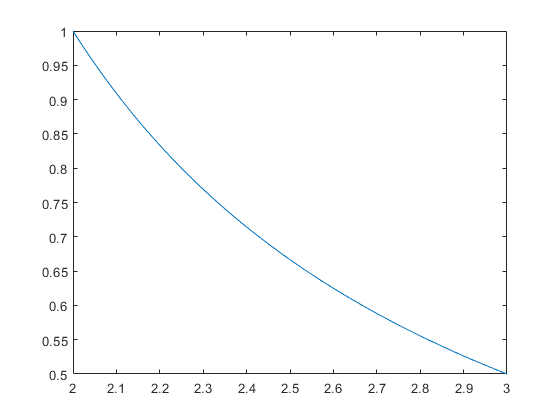

km= 3:7;
fplot(f), xlim([a b])

for n=1:size(km,2)
    m(n).MONT= monteCarlo(f,a,b,0,1,10^km(n));
    m(n).err= abs(log(2)-m(n).MONT);
end
m

m = 1×5 struct array with fields:
    MONT
    err


## Apartado D

format short g
for n=1:size(TRAP,2)
    xf(n)= correctDec(TRAP(n),log(2));
end
[AT RT]= funerror(TRAP,ones(1,size(TRAP,2))*log(2));
TT=table(AT',RT',xf'); TT.Properties.VariableNames = {'errorAbsolutTrap','errorRelatiuTrap','xifresTrap'}

TT = 6×3 table
    errorAbsolutTrap    errorRelatiuTrap    xifresTrap
    ________________    ________________    __________

         0.056853            0.082021           0     
         0.015186            0.021909           1     
        0.0038766           0.0055928           2     
       0.00097467           0.0014062           2     
       0.00024402          0.00035205           3     
       6.1028e-05          8.8044e-05           3     


for n=1:size(romb1,2)
    xf(n)= correctDec(romb1(n),log(2));
end
[AT RT]= funerror(romb1,ones(1,size(romb1,2))*log(2));
TT=table(AT',RT',xf'); TT.Properties.VariableNames = {'errorAbsolutRomb1','errorRelatiuRomb1','xifresRomb1'}

TT = 6×3 table
    errorAbsolutRomb1    errorRelatiuRomb1    xifresRomb1
    _________________    _________________    ___________

         0.056853             0.082021             0     
         0.015186             0.021909             1     
        0.0038766            0.0055928             2     
       0.00097467            0.0014062             2     
       0.00024402           0.00035205             3     
       6.1028e-05           8.8044e-05             3     


for n=1:size(romb2,2)
    xf(n)= correctDec(romb2(n),log(2));
end
[AT RT]= funerror(romb2,ones(1,size(romb2,2))*log(2));
TT=table(AT',RT',xf'); TT.Properties.VariableNames = {'errorAbsolutRomb2','errorRelatiuRomb2','xifresRomb2'}

TT = 6×3 table
    errorAbsolutRomb2    errorRelatiuRomb2    xifresRomb2
    _________________    _________________    ___________

          0.69315                    1             0     
        0.0012973            0.0018716             2     
       0.00010679           0.00015406             3     
       7.3501e-06           1.0604e-05             4     
       4.7226e-07           6.8133e-07             6     
        2.973e-08           4.2891e-08             7     


for n=1:size(romb3,2)
    xf(n)= correctDec(romb3(n),log(2));
end
[AT RT]= funerror(romb3,ones(1,size(romb3,2))*log(2));
TT=table(AT',RT',xf'); TT.Properties.VariableNames = {'errorAbsolutRomb3','errorRelatiuRomb3','xifresRomb3'}

TT = 6×3 table
    errorAbsolutRomb3    errorRelatiuRomb3    xifresRomb3
    _________________    _________________    ___________

          0.69315                    1             0     
          0.69315                    1             0     
       2.7423e-05           3.9562e-05             4     
       7.2092e-07           1.0401e-06             5     
       1.3737e-08           1.9818e-08             7     
        2.279e-10            3.288e-10             9     


for n=1:size(romb4,2)
    xf(n)= correctDec(romb4(n),log(2));
end
[AT RT]= funerror(romb4,ones(1,size(romb4,2))*log(2));
TT=table(AT',RT',xf'); TT.Properties.VariableNames = {'errorAbsolutRomb4','errorRelatiuRomb4','xifresRomb4'}

TT = 6×3 table
    errorAbsolutRomb4    errorRelatiuRomb4    xifresRomb4
    _________________    _________________    ___________

          0.69315                    1             0     
          0.69315                    1             0     
          0.69315                    1             0     
       2.9708e-07            4.286e-07             6     
        2.512e-09            3.624e-09             8     
       1.3473e-11           1.9437e-11            10     


for n=1:size(km,2)
    monte(n)= m(n).MONT;
    xM(n)= correctDec(monte(n),log(2));
end

[AT RT]= funerror(monte,ones(1,size(km,2))*log(2));
TT=table(AT',RT',xM'); TT.Properties.VariableNames = {'errorAbsolutMonte','errorRelatiuMonte','xifresMonte'}

TT = 5×3 table
    errorAbsolutMonte    errorRelatiuMonte    xifresMonte
    _________________    _________________    ___________

         0.013147             0.018967             1     
       0.00085282            0.0012304             2     
        0.0010172            0.0014675             2     
       0.00012418           0.00017915             3     
       0.00013998           0.00020195             3     
